### Acoustic Scenario

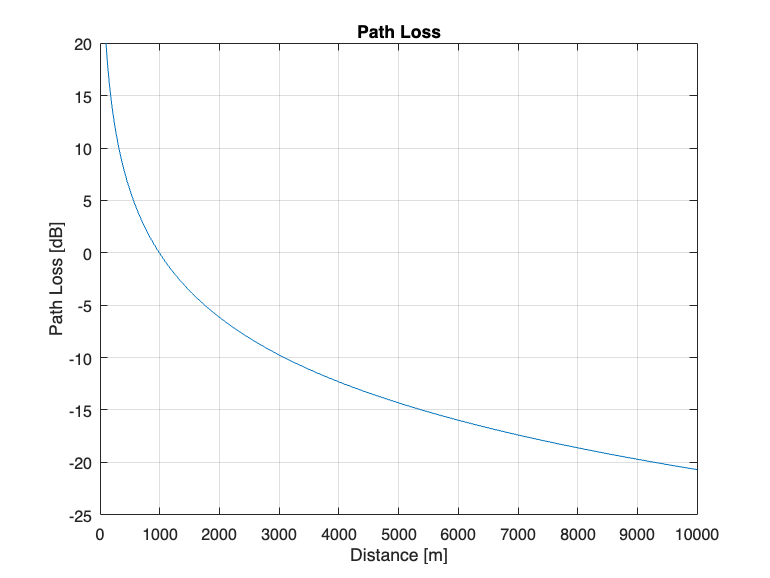

clc; clear;
f = 1;
A_0 = 0.1;
d = linspace(100, 10000, 1000);
k = 2;
a = 0.11 * f.^2 / (1 + f.^ 2) + 44 * (f.^2) / (4100 + f.^2) + 2.75e-4 * f.^2 + 0.003;
PL_acoustic = -1 * ( k * 10 * log10(d * 1e-3) + (d * 1e-3) .* a);
plot(d, PL_acoustic)
title('Path Loss')
ylabel('Path Loss [dB]')
xlabel('Distance [m]')
grid on 

### RF Scenario

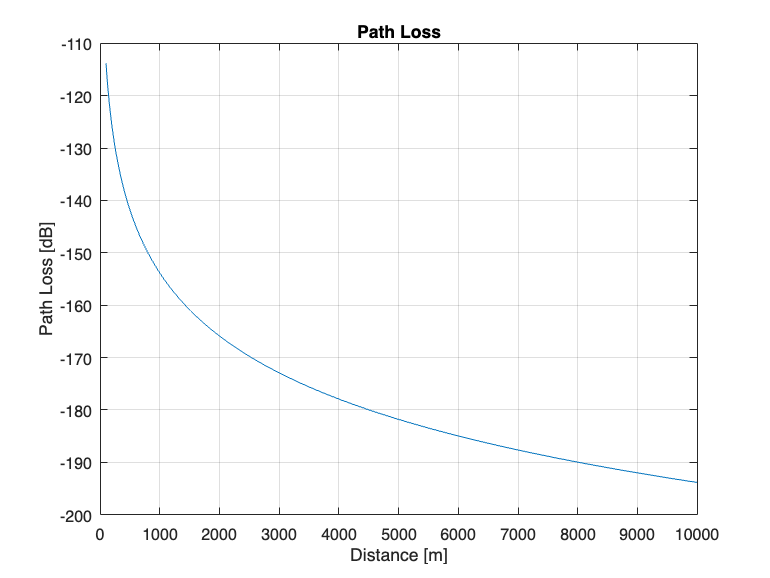

frequency = 0.9e9;
gamma = 4;
c = 2.3e8;
d_0 = 1;
path_loss_db_0 = 20 * log10(c/(4 * frequency * pi * d_0));
PL_rf = path_loss_db_0 + 10 * gamma * log10(d_0 ./ d);
plot(d, PL_rf)
title('Path Loss')
ylabel('Path Loss [dB]')
xlabel('Distance [m]')
grid on 

### Optical Scenario

lambda = 532e-9;
c_1 = 0.0657;
c_2 = 0.2634;
h_1 = 0.2;
h_2 = 0.0046;
PL_opt = mag2db(h_1 * exp(-c_1 .* d) + h_2 * exp(-c_2 .* d))

PL_opt = 1.0e+03 *

   -0.0710   -0.0767   -0.0824   -0.0880   -0.0937   -0.0993   -0.1050   -0.1106   -0.1163   -0.1219   -0.1276   -0.1333   -0.1389   -0.1446   -0.1502   -0.1559   -0.1615   -0.1672   -0.1728   -0.1785   -0.1842   -0.1898   -0.1955   -0.2011   -0.2068   -0.2124   -0.2181   -0.2237   -0.2294   -0.2350   -0.2407   -0.2464   -0.2520   -0.2577   -0.2633   -0.2690   -0.2746   -0.2803   -0.2859   -0.2916   -0.2973   -0.3029   -0.3086   -0.3142   -0.3199   -0.3255   -0.3312   -0.3368   -0.3425   -0.3482


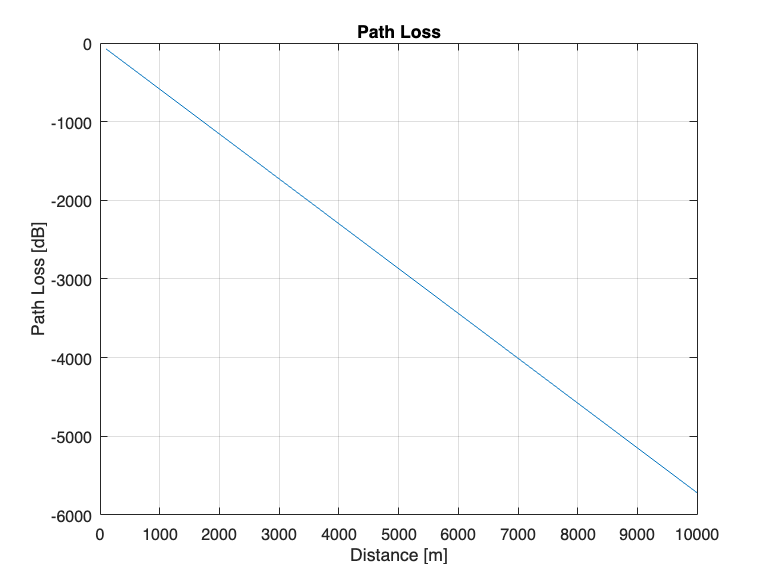

plot(d, PL_opt);
title('Path Loss')
ylabel('Path Loss [dB]')
xlabel('Distance [m]')
grid on 

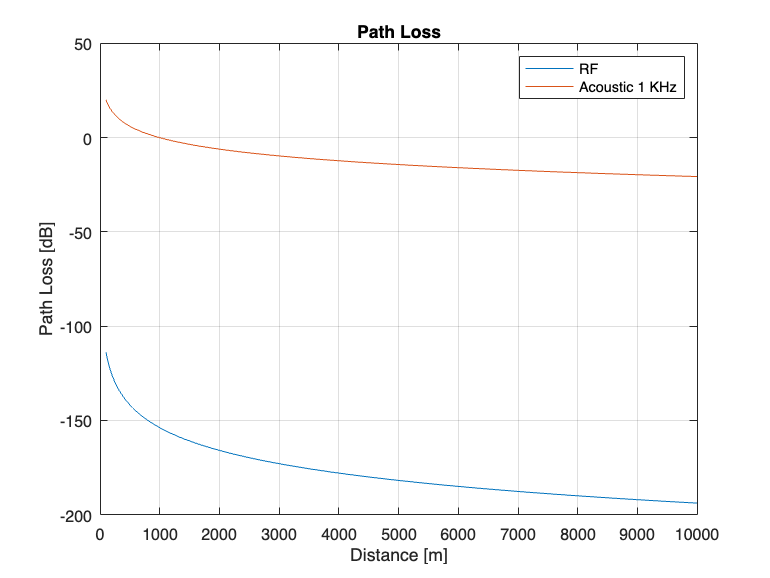

plot(d, PL_rf, d, PL_acoustic)
title('Path Loss')
ylabel('Path Loss [dB]')
xlabel('Distance [m]')
legend 'RF' 'Acoustic 1 KHz' 
grid on 